clc
clear all

load("result/theta_diff_m_throughput.mat")
load("result/gamma_diff_m_throughput.mat")

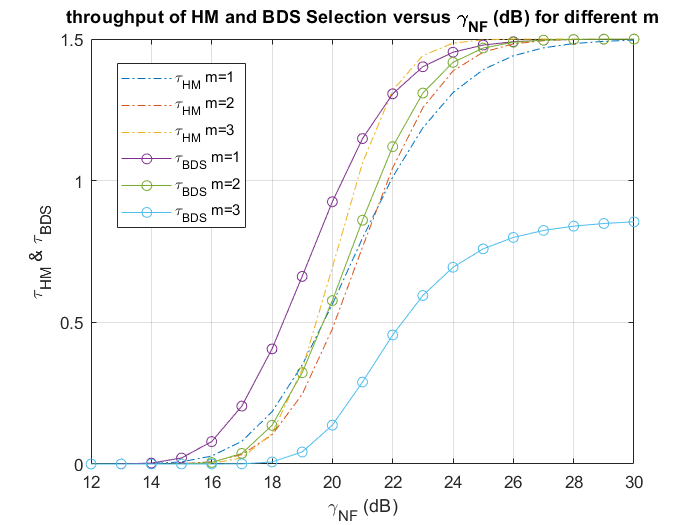

gamma_NF_db = [12:30];
gamma_NF = 10.^(gamma_NF_db/10);

figure
plot(gamma_NF_db, gamma_diff_m_throughput, '-.');
hold on
plot(gamma_NF_db, theta_diff_m_throughput, '-o');

legend({'\tau_{HM} m=1', '\tau_{HM} m=2', '\tau_{HM} m=3', '\tau_{BDS} m=1', '\tau_{BDS} m=2', '\tau_{BDS} m=3'}, 'Location', 'best')


xlabel('\gamma_{NF} (dB)'); ylabel('\tau_{HM} & \tau_{BDS}');
title('throughput of HM and BDS Selection versus \gamma_{NF} (dB) for different m')
grid on, hold on

% xlim([1 15])
% ylim([0 1.5])
xticks(12:2:30)
yticks(0:0.5:1.5)



% annotation('textarrow', [0.5,0.3], [0.4,0.7], 'String', 'N = 1,2,3,4', 'LineWidth', 0.1);